%Problem 4
a = 1.115 * 10^-3; %Thermal diffusivity(m^2/s)
U_i = 20; %Initial temperature (K)
U_o = 50; %Temperature at t > 0
x = linspace(0,1000,1000);

t = 0;
f = x./sqrt(4*a*t);
ef = erf(f);
U = U_o + ((U_i - U_o).*ef);

t_1 = 10000;
f_1 = x./sqrt(4*a*t_1);
ef_1 = erf(f_1);
U_1 = U_o + ((U_i - U_o).*ef_1);

t_2 = 100000;
f_2 = x./sqrt(4*a*t_2);
ef_2 = erf(f_2);
U_2 = U_o + ((U_i - U_o).*ef_2);

t_3 = 1000000;
f_3 = x./sqrt(4*a*t_3);
ef_3 = erf(f_3);
U_3 = U_o + ((U_i - U_o).*ef_3);

t_4 = 10000000;
f_4 = x./sqrt(4*a*t_4);
ef_4 = erf(f_4);
U_4 = U_o + ((U_i - U_o).*ef_4);

t_5 = 100000000;
f_5 = x./sqrt(4*a*t_5);
ef_5 = erf(f_5);
U_5 = U_o + ((U_i - U_o).*ef_5);

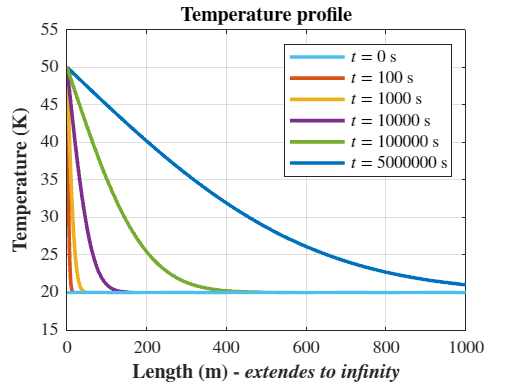

h6 = plot(x,U_5,'LineWidth',2);
ylabel('$\textbf{Temperature (K)}$','Interpreter', 'latex')
xlabel('$\textbf{Length (m) - \textit{extendes to infinity}}$', 'Interpreter', 'latex')
title('$\textbf{Temperature profile}$', 'Interpreter', 'latex');
grid on
hold on
h2 = plot(x,U_1,'LineWidth',2);
h3 = plot(x,U_2,'LineWidth',2);
h4 = plot(x,U_3,'LineWidth',2);
h5 = plot(x,U_4,'LineWidth',2);
h1 = plot(x,U,'LineWidth',2);
legend([h1, h2, h3, h4, h5, h6], {'$t = 0$ s', '$t = 100$ s', '$t = 1000$ s', '$t = 10000$ s', '$t = 100000$ s', '$t = 5000000$ s'}, 'Interpreter', 'latex');
ylim([15, 55]);
set(gca, 'TickLabelInterpreter', 'latex');

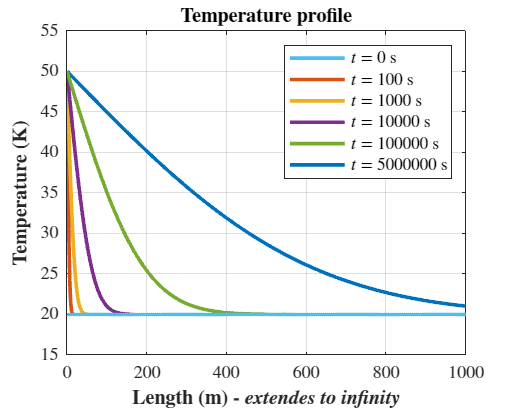

%Saving plot
outputFileName = 'Problem_4.png';
figureHandle = gcf;
figureWidth = 1000; % in pixels
figureHeight = 800; % in pixels
set(figureHandle, 'Position', [100, 100, figureWidth, figureHeight]); 
print(figureHandle, outputFileName, '-dpng', '-r600');